# Question 4

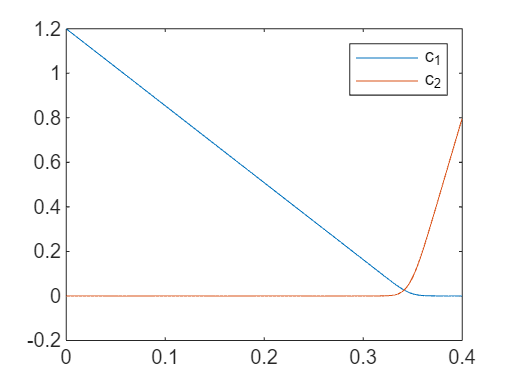

xmesh=linspace(0,0.4,50); %c
solinit=bvpinit(xmesh,[2 2 2 2]); %c
sol=bvp4c(@bvpfcn,@bcfn,solinit);
plot(sol.x,sol.y(1,:));
hold on;
plot(sol.x,sol.y(2,:));
hold off;
legend('c_1','c_2');

function res=bcfn(ya,yb)
    res=[ya(1)-1.2
        yb(1)
        ya(2)
        yb(2)-0.8];
end
function res=bvpfcn(x,y)
    D1=1.99e-5;
    D2=4.55e-6;
    k=3.33;
    res=zeros(4,1);
    res(1)=y(3); % c1'
    res(2)=y(4); % c2'
    res(3)=k*y(1)*y(2)/D1; %c1
    res(4)=k*y(1)*y(2)/D2; %c2
end

## Question 2

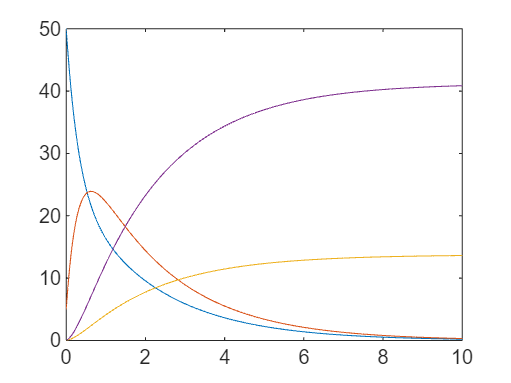

[t,c1]=ode45(@f,[0,10],[50 5 0 0]);
plot(t,c1);

[t_max,cb_max]=max(c1(:,2));
disp(t_max);

   23.9194



function res=f(~,c)
    k1=2;k2=1;k3=0.2;k4=0.6;
    res=zeros(4,1);
    res(1)=k2*c(2)-k1*c(1);
    res(2)=k1*c(1)-(k2+k3+k4)*c(2);
    res(3)=k3*c(2);
    res(4)=k4*c(2);
end